## BIV-Übung 2

Hadi Saleh 1822230

### 1 Histogramme bei Farbbildern: einzelne Farbkanäle; Kontrast

a)

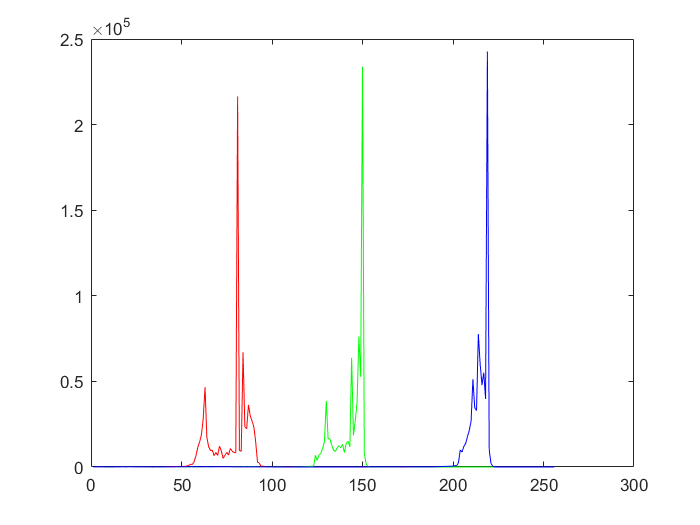

moewe=imread('moewex.jpg');
red = moewe(:, :, 1);
green = moewe(:, :, 2);
blue = moewe(:, :, 3);
figure
rHist = imhist(red);
gHist = imhist(green);
bHist = imhist(blue);
title('test')
plot(rHist, 'r')
hold on
plot(gHist, 'g')
plot(bHist, 'b')

b)

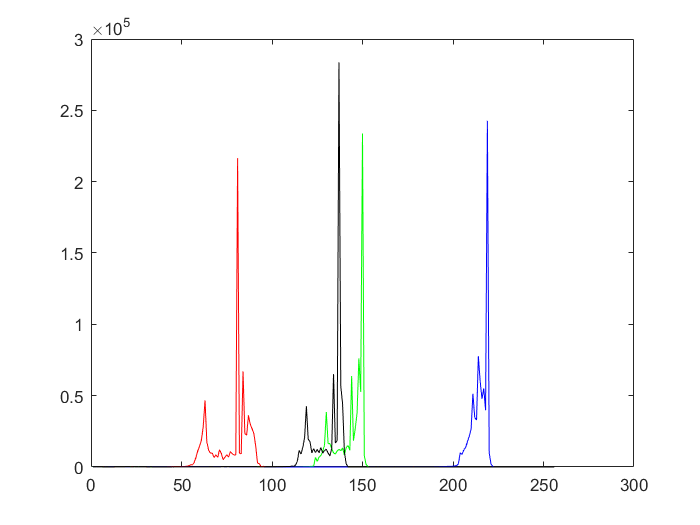

grey = rgb2gray(moewe);
kHist = imhist(grey);
plot(kHist, 'k')

Folgender Luminance-Formel wird benutzt um die Helligkeit zu berechnen:

`L = 0.2989 * R + 0.5870 * G + 0.1140 * B`

`c)`

gMin = min(grey(:))

gMin = uint8
0

gMax= max(grey(:))

gMax = uint8
246

globalContrast = double(gMax - gMin) / double(255)

globalContrast = 0.9647

d)

gQuantile = stretchlim(grey(:))

gQuantile =     0.3373
    0.5451


globalContrastQuantile = gQuantile(2) - gQuantile(1)

globalContrastQuantile = 0.2078